# Meat Quality Control - Computer Vision UPC

## Xavier Martín Ballesteros and Adrià Cabeza Sant'Anna

### 1. Seleccionar manualment una regió d’interès rectangular, de forma que s’elimini la part inferior de la imatge on reposa la llonza.

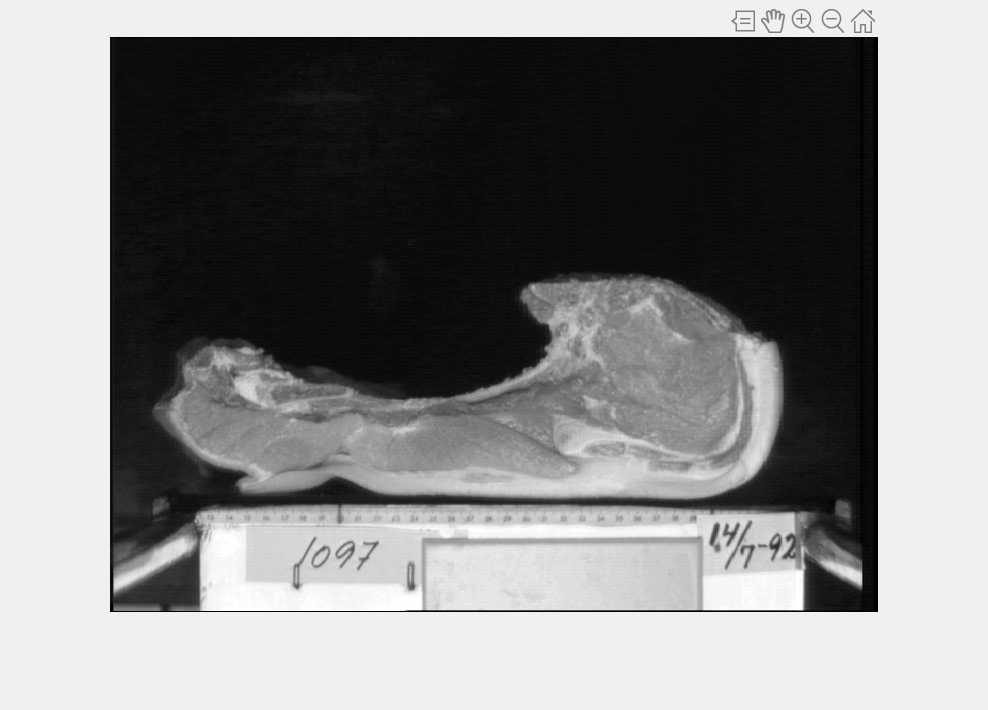

clear all;
close all;
im = imcrop(imread('F1097flb.bmp'));

%im = imread('lena.jpg');
%im = im(:, :, 1)/3 + im(:, :, 2)/3 + im(:, :, 3)/3;
% imshow(im)

% TODO: RETALLAT? COM LLEGIR TOTES LES IMATGES?
%J = imcrop(im);
%imshow(J)

###  2) Implementar un petit programa que binaritzi les imatges a partir d’un llindar programable per l’usuari. Trobar el % de píxels de greix.  El % de greix cal trobar-lo respecte dels píxels totals de la llonza. Per tant, abans de fer el càlcul cal eliminar els píxels del fons.

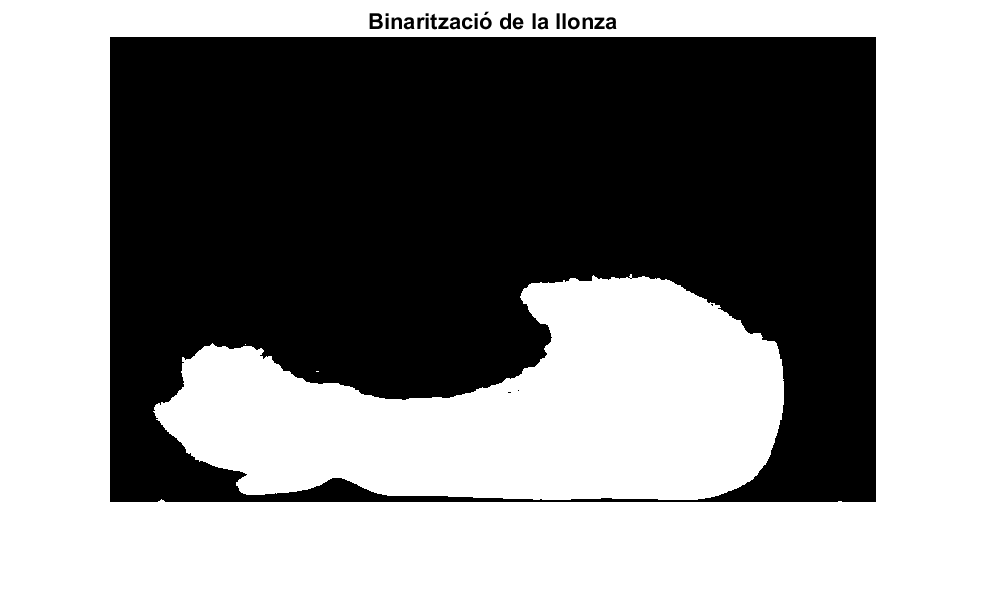


% Agafem només la llonza
llindar_llonza = 65/256;
im_llonza = im;
% im_llonza(im_llonza > llindar_llonza) = 255;
% im_llonza(im_llonza <= llindar_llonza) = 0;
im_llonza = imbinarize(im_llonza, llindar_llonza);
figure, imshow(im_llonza), title('Binarització de la llonza')

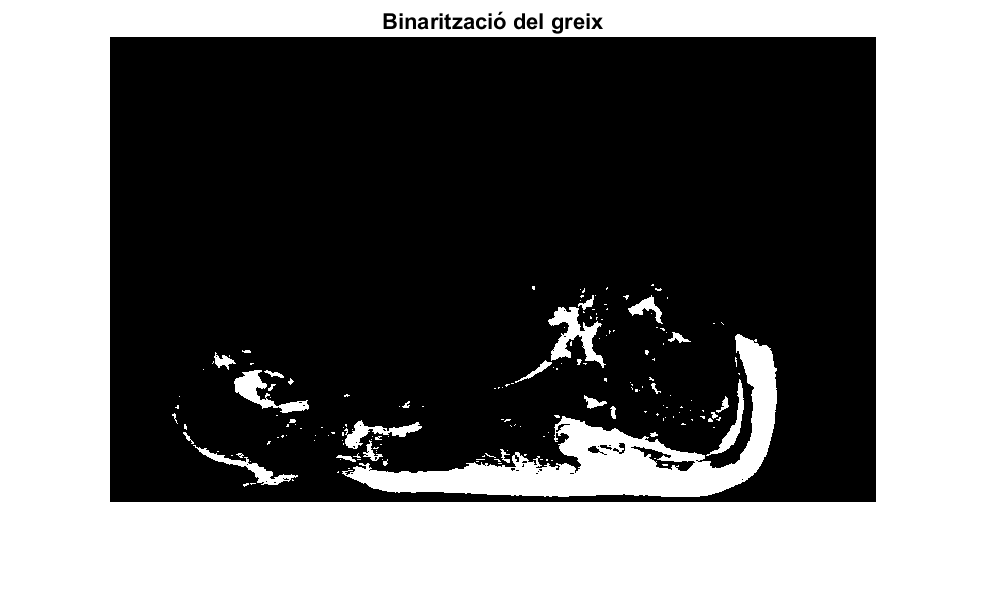


% Agafem només el greix
llindar_greix = 160/256;
im_greix = im;
% im_greix(im_greix>llindar_greix) = 255;
% im_greix(im_greix<=llindar_greix) = 0;
% Si utilitzem això hem de diidir el llindar per 256
im_greix = imbinarize(im_greix, llindar_greix);
figure, imshow(im_greix), title('Binarització del greix')


px_llonza = size(im_llonza(im_llonza), 1);
px_greix = size(im_greix(im_greix), 1);

percentatge_greix = (px_greix/px_llonza) * 100

percentatge_greix = 27.5551

### 3) Extraure l’histograma de les imatges. Trobar el llindar a ull a partir de l’histograma.

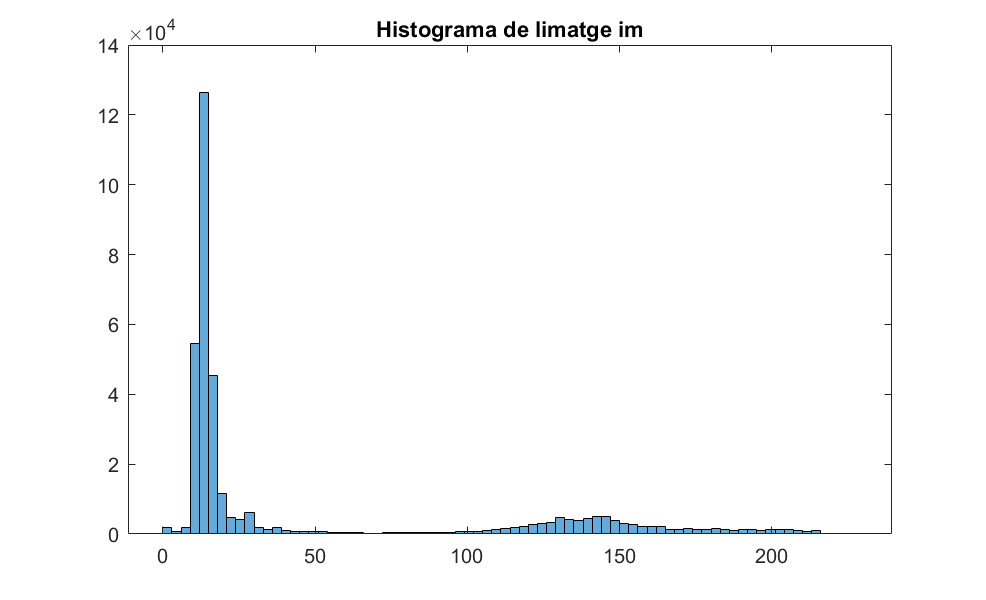

 %(Aquest histograma ens dona un interval de possibles llindars). PENSAR
 %QUE LO QUE HEM FET A L'EXERCICI 2 VA SER A PARTIR DEL HISTOGRAMA
histogram(im), title('Histograma de limatge im');

### 4) Trobar el llindar de forma automàtica. Podeu usar ‘graythresh’ de MATLAB. 

llindar_otsu_llonza = graythresh(im)

llindar_otsu_llonza = 0.3137

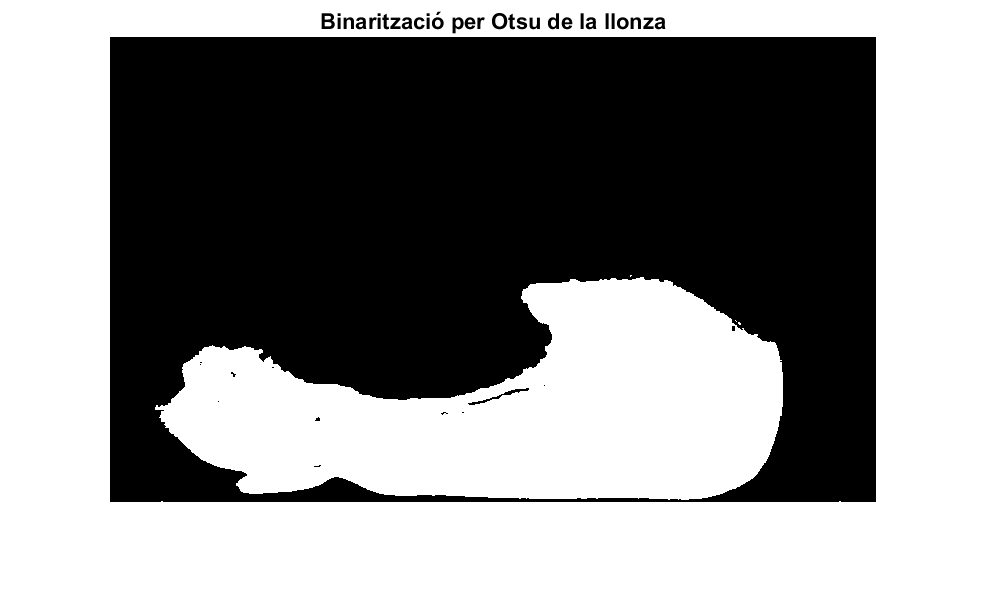

im_otsu_llonza = imbinarize(im, llindar_otsu_llonza);
figure, imshow(im_otsu_llonza), title('Binarització per Otsu de la llonza')

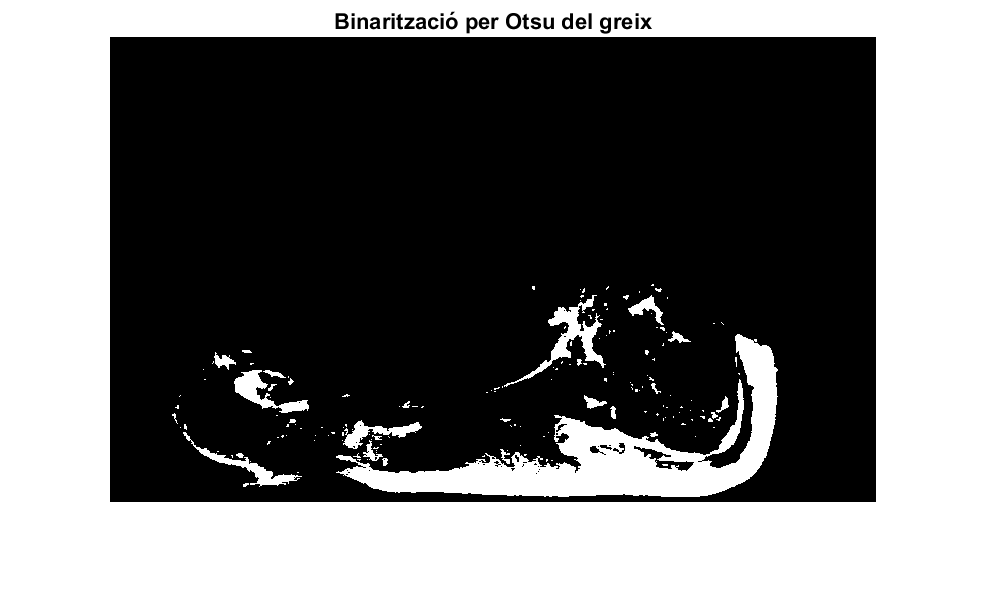


% llindar_otsu_llonza between 0 and 1
mask = im(im >= llindar_otsu_llonza * 256);
llindar_otsu_greix = graythresh(mask);
im_otsu_greix = imbinarize(im, llindar_otsu_greix);
figure, imshow(im_otsu_greix), title('Binarització per Otsu del greix')


px_llonza_otsu = size(im_otsu_llonza(im_otsu_llonza), 1);
px_greix_otsu = size(im_otsu_greix(im_otsu_greix), 1);

percentatge_greix_otsu = (px_greix_otsu/px_llonza_otsu) * 100

percentatge_greix_otsu = 29.1365

### 5) Trobar el llindar utilitzant algun altre mètode. Implementeu com a mínim dos mètodes diferents.

## Optimal Thresholding

% Optimal thresholding => http://www.pvv.org/~perchrh/papers/datasyn/paper2/report.pdf
llindar_optimal_llonza = OptimalRidlerCalvard(im, 0)

llindar_optimal_llonza = 0.3158

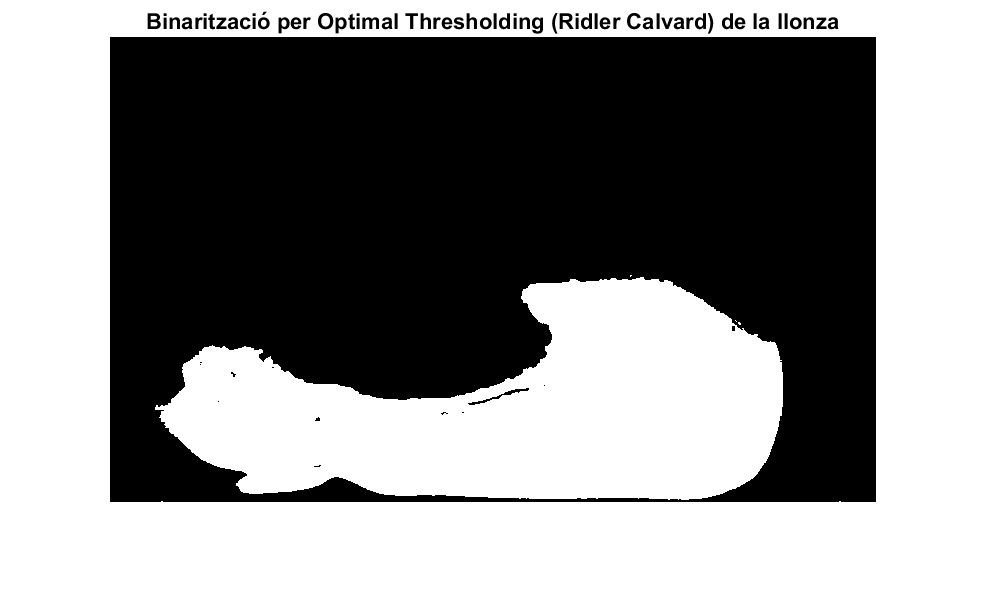

im_optimal_llonza = imbinarize(im, llindar_optimal_llonza);
figure, imshow(im_optimal_llonza), title('Binarització per Optimal Thresholding (Ridler Calvard) de la llonza')

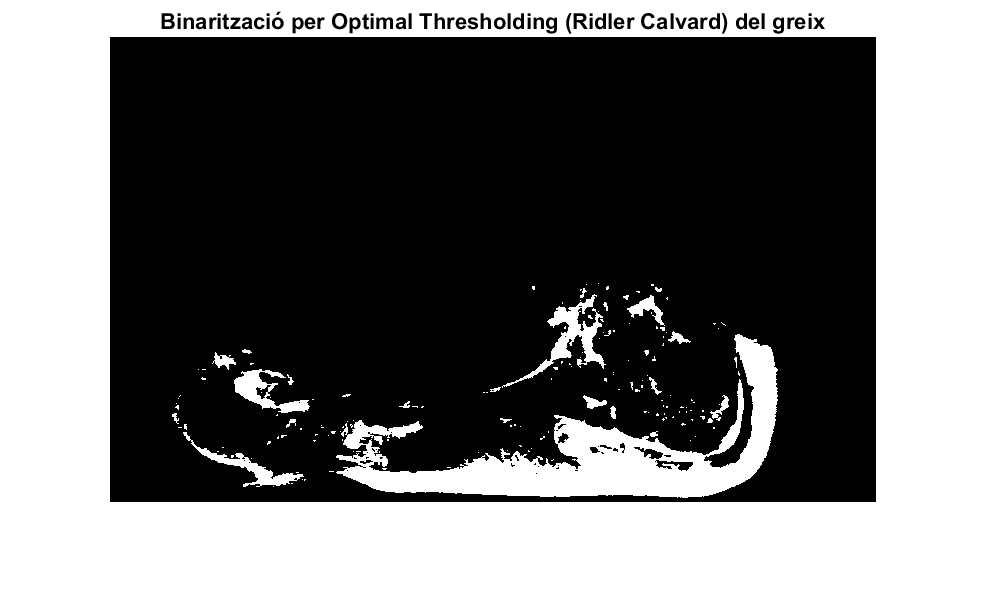


mask = im(im >= llindar_optimal_llonza * 256);
llindar_optimal_greix = OptimalRidlerCalvard(mask, 0);
im_optimal_greix = imbinarize(im, llindar_optimal_greix);
figure, imshow(im_optimal_greix), title('Binarització per Optimal Thresholding (Ridler Calvard) del greix')


px_llonza_optimal = size(im_optimal_llonza(im_optimal_llonza), 1);
px_greix_optimal = size(im_optimal_greix(im_optimal_greix), 1);

percentatge_greix_optimal = (px_greix_optimal/px_llonza_optimal) * 100

percentatge_greix_optimal = 31.1979

## Kapur thresholding

% Kapur, Sahoo, and Wong thresholding => https://eprints.ucm.es/16932/1/Tesis_Master_Daniel_Martin_Carabias.pdf
%https://atenea.upc.edu/pluginfile.php/2704579/mod_resource/content/2/sahoo88.pdf
llindar_entropia_llonza = KSW(im)

llindar_entropia_llonza = 0.5898

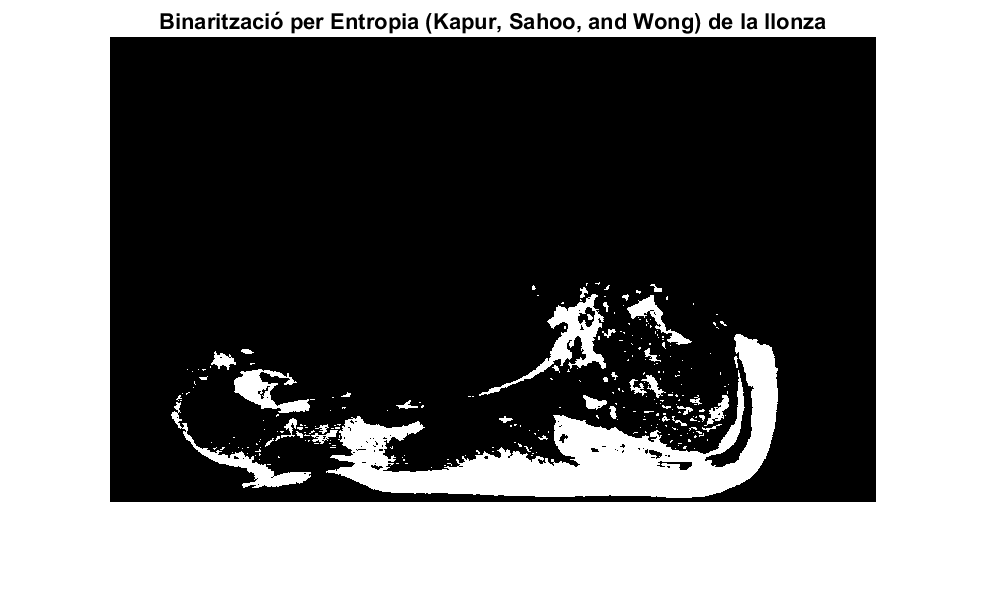

im_entropia_llonza = imbinarize(im, llindar_entropia_llonza);
figure, imshow(im_entropia_llonza), title('Binarització per Entropia (Kapur, Sahoo, and Wong) de la llonza')


mask = im(im >= llindar_entropia_llonza * 256);
llindar_entropia_greix = KSW(mask)

llindar_entropia_greix = 0.7148

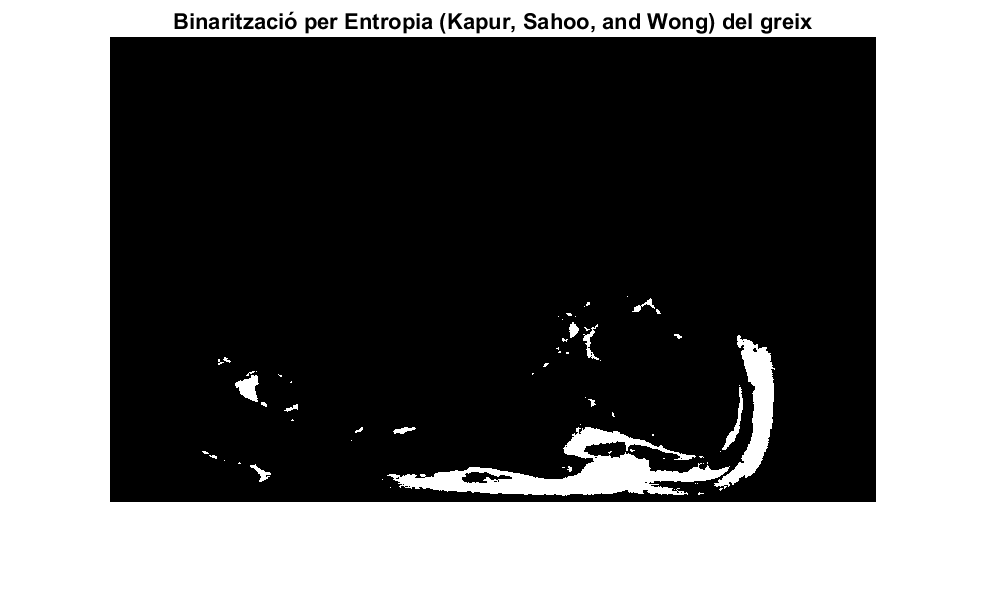

im_entropia_greix = imbinarize(im, llindar_entropia_greix);
figure, imshow(im_entropia_greix), title('Binarització per Entropia (Kapur, Sahoo, and Wong) del greix')


px_llonza_entropia = size(im_entropia_llonza(im_entropia_llonza), 1);
px_greix_entropia = size(im_entropia_greix(im_entropia_greix), 1);

percentatge_greix_entropia = (px_greix_entropia/px_llonza_entropia) * 100

percentatge_greix_entropia = 39.6181

## P-tile thresholding

% P-tile-thresholding
[rows cols] = size(im);
total_pixels = rows * cols;
avg = size(im_otsu_llonza(im_otsu_llonza == 0), 1)/total_pixels + size(im_optimal_llonza(im_optimal_llonza == 0), 1)/total_pixels; % + size(im_entropia_llonza(im_entropia_llonza == 0), 1)/total_pixels;
avg = avg/2;
percentage = (1 - avg);
llindar_ptile_llonza = Ptile(im, percentage)

llindar_ptile_llonza = 0.3203

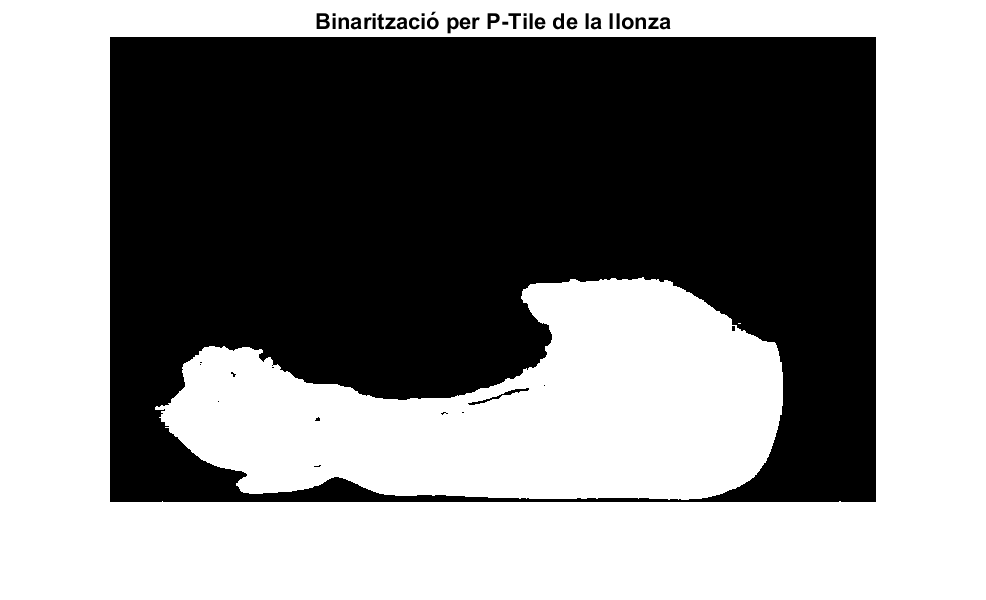

im_ptile_llonza = imbinarize(im, llindar_ptile_llonza);
figure, imshow(im_ptile_llonza), title('Binarització per P-Tile de la llonza')

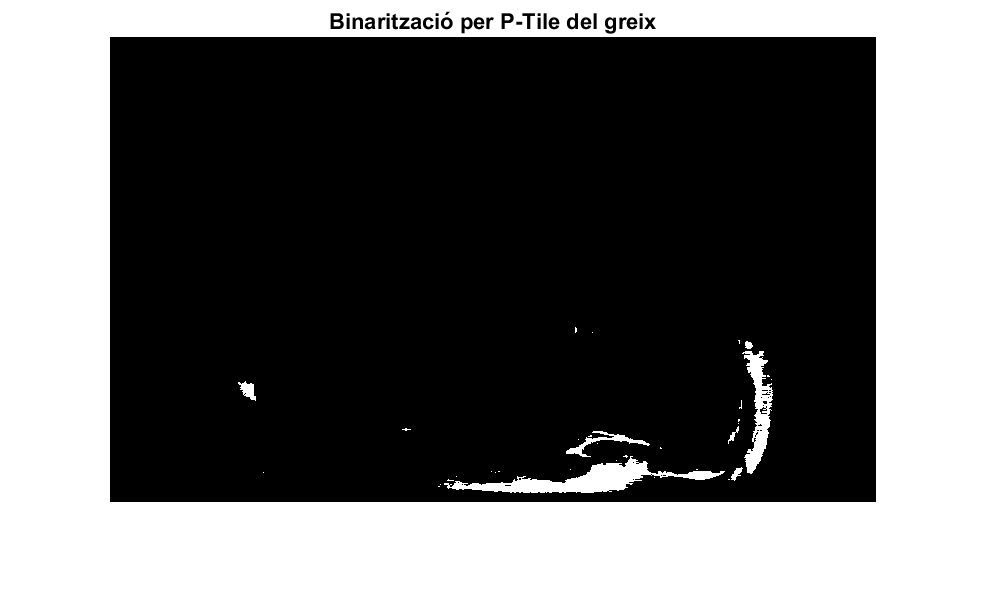


avg = size(im_otsu_greix(im_otsu_greix == 0), 1)/total_pixels + size(im_optimal_greix(im_optimal_greix == 0), 1)/total_pixels; % + size(im_entropia_greix(im_entropia_greix == 0), 1)/total_pixels;
avg = avg/2;
percentage = (1 - avg);
mask = im(im >= llindar_ptile_llonza * 256);
llindar_ptile_greix = Ptile(mask, percentage);
im_ptile_greix = imbinarize(im, llindar_ptile_greix);
figure, imshow(im_ptile_greix), title('Binarització per P-Tile del greix')


px_llonza_ptile = size(im_ptile_llonza(im_ptile_llonza), 1);
px_greix_ptile = size(im_ptile_greix(im_ptile_greix), 1);

percentatge_greix_ptile = (px_greix_ptile/px_llonza_ptile) * 100

percentatge_greix_ptile = 6.7263